# Integrare numerica

## Probleme

P1. Implementati formula repetata a trapezului, dreptunghiului si a lui Simpson.

% definim o functie pentru test
f = @(x) sin(x) .* exp(-x.^2 / 2);
a = 0; b = pi;
n = 20;

% apelam cele trei metode si comparam rezultatele
fprintf('===== Comparatie metode de baza =====\n');

===== Comparatie metode de baza =====


rezultat_trapez = formula_trapez(f, a, b, n);
rezultat_simpson = formula_simpson(f, a, b, n);
rezultat_dreptunghiuri = formula_dreptunghiuri(f, a, b, n);

fprintf('trapez (n=%d): %.10f\n', n, rezultat_trapez);

trapez (n=20): 0.7232454925


fprintf('simpson (n=%d): %.10f\n', n, rezultat_simpson);

simpson (n=20): 0.7253328671


fprintf('dreptunghiuri (n=%d): %.10f\n', n, rezultat_dreptunghiuri);

dreptunghiuri (n=20): 0.7263580016



% verificam cu functia matlab pentru comparatie
rezultat_matlab = integral(f, a, b);
fprintf('matlab integral: %.10f\n\n', rezultat_matlab);

matlab integral: 0.7253196878



P2. Concepeti o reprezentare grafica intuitiva pentru formula trapezelor si formula repetata a lui Simpson (facultativ).

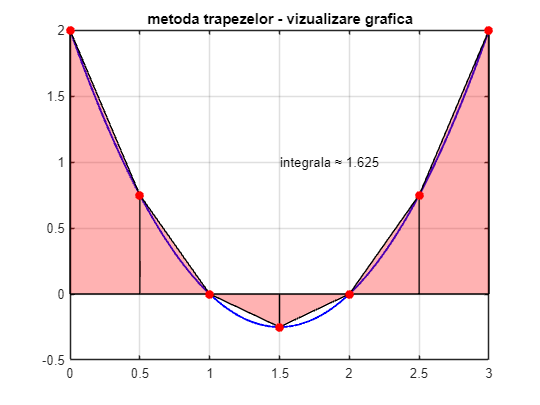

% exemplu functie polinomiala pentru vizualizare clara
f_viz = @(x) x.^2 - 3*x + 2;
a_viz = 0; b_viz = 3;
n_viz = 6;

% apelam functiile de vizualizare
vizualizare_trapez(f_viz, a_viz, b_viz, n_viz);
vizualizare_simpson(f_viz, a_viz, b_viz, n_viz);

% adaugam titluri descriptive
figure(1); title('metoda trapezelor - vizualizare grafica');

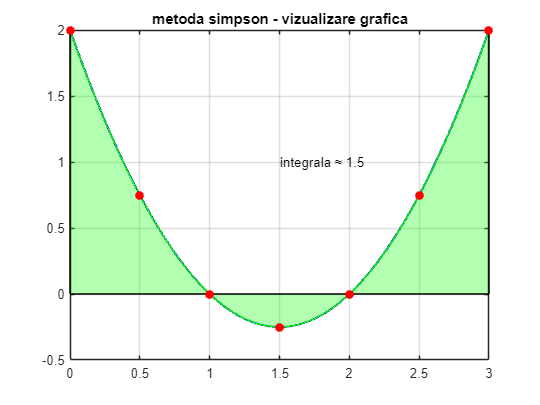

figure(2); title('metoda simpson - vizualizare grafica');

P3. Implementati o metoda de cuadratura adaptiva pentru formula repetata a lui Simpson, una pentru metoda trapezelor si una pentru metoda dreptunghiurilor.

% functie cu oscilatie mare pentru a demonstra avantajele metodelor adaptive
f_osc = @(x) sin(10*x) .* exp(-x/5);
a_osc = 0; b_osc = 2*pi;
tol = 1e-6;

fprintf('===== Metode adaptive =====\n');

===== Metode adaptive =====


tic; rezultat_adaptiv_trapez = adaptiv_trapez(f_osc, a_osc, b_osc, tol); t1 = toc;
tic; rezultat_adaptiv_simpson = adaptiv_simpson(f_osc, a_osc, b_osc, tol); t2 = toc;
tic; rezultat_adaptiv_dreptunghiuri = adaptiv_dreptunghiuri(f_osc, a_osc, b_osc, tol); t3 = toc;

fprintf('adaptiv trapez: %.10f (timp: %.4f s)\n', rezultat_adaptiv_trapez, t1);

adaptiv trapez: 0.0715104414 (timp: 0.6278 s)


fprintf('adaptiv simpson: %.10f (timp: %.4f s)\n', rezultat_adaptiv_simpson, t2);

adaptiv simpson: 0.0715104416 (timp: 0.0186 s)


fprintf('adaptiv dreptunghiuri: %.10f (timp: %.4f s)\n', rezultat_adaptiv_dreptunghiuri, t3);

adaptiv dreptunghiuri: 0.0715104408 (timp: 0.3804 s)



% comparam cu functiile matlab
tic; rezultat_quad = quad(f_osc, a_osc, b_osc); t4 = toc;
tic; rezultat_integral = integral(f_osc, a_osc, b_osc); t5 = toc;
fprintf('matlab quad: %.10f (timp: %.4f s)\n', rezultat_quad, t4);

matlab quad: 0.0715106592 (timp: 0.0014 s)


fprintf('matlab integral: %.10f (timp: %.4f s)\n\n', rezultat_integral, t5);

matlab integral: 0.0715104415 (timp: 0.0019 s)



P4. Implementati metoda lui Romberg.

f_rom = @(x) 1./(1+x.^2);  % functia are primitiva arctan(x)
a_rom = 0; b_rom = 1;
tol_rom = 1e-10;
max_iter = 10;

fprintf('===== Metoda Romberg =====\n');

===== Metoda Romberg =====


[R, iteratii] = romberg(f_rom, a_rom, b_rom, tol_rom, max_iter);

% afisam matricea romberg in format tabelar
fprintf('Matricea Romberg:\n');

Matricea Romberg:


for i = 1:iteratii
    for j = 1:i
        fprintf('%14.10f ', R(i,j));
    end
    fprintf('\n');
end

  0.7500000000   0.7750000000   0.7833333333   0.7827941176   0.7853921569   0.7855294118   0.7847471236   0.7853981256   0.7853985235   0.7853964459   0.7852354030   0.7853981628   0.7853981653   0.7853981596   0.7853981663   0.7853574733   0.7853981634   0.7853981634   0.7853981634   0.7853981634   0.7853981634   0.7853879909   0.7853981634   0.7853981634   0.7853981634   0.7853981634   0.7853981634   0.7853981634 


valoare_exacta = atan(1);  % pi/4
fprintf('Rezultat final: %.10f (dupa %d iteratii)\n', R(iteratii, iteratii), iteratii);

Rezultat final: 0.7853981634 (dupa 7 iteratii)


fprintf('Valoare exacta: %.10f\n', valoare_exacta);

Valoare exacta: 0.7853981634


fprintf('Eroare: %.10e\n\n', abs(R(iteratii, iteratii) - valoare_exacta));

Eroare: 1.7652546092e-14



P5. Implementati adquad, algoritmul 1.

% functie cu singularitate slaba
f_adq1 = @(x) log(x);
a_adq1 = 1e-10; b_adq1 = 1;
tol_adq = 1e-6;

% functie oscilanta
f_adq2 = @(x) sin(20*x).*exp(-x);
a_adq2 = 0; b_adq2 = 10;

fprintf('===== Algoritm adquad =====\n');

===== Algoritm adquad =====


tic; rezultat_adquad1 = adquad(f_adq1, a_adq1, b_adq1, tol_adq); t6 = toc;
tic; rezultat_adquad2 = adquad(f_adq2, a_adq2, b_adq2, tol_adq); t7 = toc;

fprintf('adquad pentru log(x): %.10f (timp: %.4f s)\n', rezultat_adquad1, t6);

adquad pentru log(x): -1.0000004201 (timp: 0.0008 s)


fprintf('adquad pentru functie oscilanta: %.10f (timp: %.4f s)\n', rezultat_adquad2, t7);

adquad pentru functie oscilanta: 0.0375640311 (timp: 0.0008 s)



% comparam cu matlab
tic; rezultat_matlab1 = integral(f_adq1, a_adq1, b_adq1); t8 = toc;
tic; rezultat_matlab2 = integral(f_adq2, a_adq2, b_adq2); t9 = toc;
fprintf('matlab pentru log(x): %.10f (timp: %.4f s)\n', rezultat_matlab1, t8);

matlab pentru log(x): -1.0000000089 (timp: 0.0027 s)


fprintf('matlab pentru functie oscilanta: %.10f (timp: %.4f s)\n\n', rezultat_matlab2, t9);

matlab pentru functie oscilanta: 0.0498743074 (timp: 0.0023 s)



## Probleme practice

P1. Generati formule Newton-Cotes inchise pentru un numar de noduri dat.

%% 6. generare formule newton-cotes inchise
fprintf('===== Formule Newton-Cotes =====\n');

===== Formule Newton-Cotes =====


for n = 2:6
    [coef, eroare] = newton_cotes(n);
    fprintf('Formula cu %d noduri:\n', n);
    fprintf('  Coeficienti: ');
    fprintf('%.6f ', coef);
    fprintf('\n  Estimare eroare: %s\n\n', eroare);
end

Formula cu 2 noduri:


  Coeficienti: 

1.000000 -0.500000 


  Estimare eroare: C * h^3 * f^(2)(ξ)



Formula cu 3 noduri:


  Coeficienti: 

1.000000 -1.333333 0.666667 


  Estimare eroare: C * h^5 * f^(4)(ξ)



Formula cu 4 noduri:


  Coeficienti: 

1.000000 -2.250000 2.625000 -1.125000 


  Estimare eroare: C * h^5 * f^(4)(ξ)



Formula cu 5 noduri:


  Coeficienti: 

1.000000 -3.200000 6.133333 -5.866667 2.133333 


  Estimare eroare: C * h^7 * f^(6)(ξ)



Formula cu 6 noduri:


  Coeficienti: 

1.000000 -4.166667 11.319444 -17.534722 13.888889 -4.340278 


  Estimare eroare: C * h^7 * f^(6)(ξ)



P2. Testati rutinele de integrare de la aceasta tema pentru diverse functii a caror primitiva nu este exprimabila prin functii elementare si comparati rezultatele cu cele furnizate de functiile MATLAB quad si integral.

functii_test = {
    @(x) exp(-x.^2), % integrala gaussiana
    @(x) sin(x)./x,  % functie cu singularitate removibila
    @(x) sqrt(1 + x.^3), % radical
    @(x) exp(sin(x.^2)) % compozitie complexa
};

nume_functii = {
    'exp(-x^2)', 
    'sin(x)/x (calculat pentru x>1e-10)', 
    'sqrt(1+x^3)', 
    'exp(sin(x^2))'
};

intervale = {
    [0, 1],  % pentru gaussiana
    [1e-10, 1],  % pentru sin(x)/x, evitam singularitatea
    [0, 2],  % pentru radical
    [0, pi]  % pentru compozitie
};

fprintf('===== Comparatie metode pentru functii fara primitiva elementara =====\n');

===== Comparatie metode pentru functii fara primitiva elementara =====


for i = 1:length(functii_test)
    f = functii_test{i};
    a = intervale{i}(1); b = intervale{i}(2);
    
    fprintf('Functie: %s, interval [%.2f, %.2f]\n', nume_functii{i}, a, b);
    
    % comparam toate metodele
    tic; r1 = formula_simpson(f, a, b, 100); t1 = toc;
    tic; r2 = adaptiv_simpson(f, a, b, 1e-6); t2 = toc;
    tic; [R, it] = romberg(f, a, b, 1e-6, 10); r3 = R(it, it); t3 = toc;
    tic; r4 = adquad(f, a, b, 1e-6); t4 = toc;
    tic; r5 = quad(f, a, b); t5 = toc;
    tic; r6 = integral(f, a, b); t6 = toc;
    
    fprintf('  Simpson(n=100): %.10f (%.4f s)\n', r1, t1);
    fprintf('  Adaptiv Simpson: %.10f (%.4f s)\n', r2, t2);
    fprintf('  Romberg: %.10f (%d iteratii, %.4f s)\n', r3, it, t3);
    fprintf('  Adquad: %.10f (%.4f s)\n', r4, t4);
    fprintf('  MATLAB quad: %.10f (%.4f s)\n', r5, t5);
    fprintf('  MATLAB integral: %.10f (%.4f s)\n\n', r6, t6);
end

Functie: exp(-x^2), interval [0.00, 1.00]


  Simpson(n=100): 0.7468241329 (0.0009 s)


  Adaptiv Simpson: 0.7468241406 (0.0004 s)


  Romberg: 0.7468241331 (5 iteratii, 0.0014 s)


  Adquad: 0.7468241347 (0.0002 s)


  MATLAB quad: 0.7468241807 (0.0051 s)


  MATLAB integral: 0.7468241328 (0.0010 s)



Functie: sin(x)/x (calculat pentru x>1e-10), interval [0.00, 1.00]


  Simpson(n=100): 0.9460830703 (0.0014 s)


  Adaptiv Simpson: 0.9460830853 (0.0005 s)


  Romberg: 0.9460830703 (4 iteratii, 0.0003 s)


  Adquad: 0.9460830703 (0.0002 s)


  MATLAB quad: 0.9460830700 (0.0007 s)


  MATLAB integral: 0.9460830703 (0.0007 s)



Functie: sqrt(1+x^3), interval [0.00, 2.00]


  Simpson(n=100): 3.2413092602 (0.0010 s)


  Adaptiv Simpson: 3.2413092536 (0.0008 s)


  Romberg: 3.2413092677 (6 iteratii, 0.0002 s)


  Adquad: 3.2413092584 (0.0010 s)


  MATLAB quad: 3.2413092037 (0.0006 s)


  MATLAB integral: 3.2413092632 (0.0004 s)



Functie: exp(sin(x^2)), interval [0.00, 3.14]


  Simpson(n=100): 4.6995188851 (0.0009 s)


  Adaptiv Simpson: 4.6995196112 (0.0046 s)


  Romberg: 4.6995196143 (9 iteratii, 0.0005 s)


  Adquad: 4.6995196017 (0.0002 s)


  MATLAB quad: 4.6995195999 (0.0008 s)


  MATLAB integral: 4.6995196146 (0.0007 s)




%% 8. studiu de convergenta
f_conv = @(x) exp(sin(x));
a_conv = 0; b_conv = pi;
valoare_referinta = integral(f_conv, a_conv, b_conv);

n_values = [4, 8, 16, 32, 64, 128, 256, 512];
erori_trapez = zeros(size(n_values));
erori_simpson = zeros(size(n_values));
erori_dreptunghiuri = zeros(size(n_values));

fprintf('===== Studiu de convergenta =====\n');

===== Studiu de convergenta =====


fprintf('Functie: exp(sin(x)) pe [0, pi]\n');

Functie: exp(sin(x)) pe [0, pi]


fprintf('Valoare de referinta: %.15f\n\n', valoare_referinta);

Valoare de referinta: 6.208758035711109




fprintf('n\tEroare Trapez\tEroare Simpson\tEroare Dreptunghiuri\n');

n	Eroare Trapez	Eroare Simpson	Eroare Dreptunghiuri


fprintf('--------------------------------------------------------\n');

--------------------------------------------------------



for i = 1:length(n_values)
    n = n_values(i);
    
    r_trapez = formula_trapez(f_conv, a_conv, b_conv, n);
    r_simpson = formula_simpson(f_conv, a_conv, b_conv, n);
    r_dreptunghiuri = formula_dreptunghiuri(f_conv, a_conv, b_conv, n);
    
    erori_trapez(i) = abs(r_trapez - valoare_referinta);
    erori_simpson(i) = abs(r_simpson - valoare_referinta);
    erori_dreptunghiuri(i) = abs(r_dreptunghiuri - valoare_referinta);
    
    fprintf('%d\t%.2e\t%.2e\t%.2e\n', n, erori_trapez(i), erori_simpson(i), erori_dreptunghiuri(i));
end

4	1.03e-01	1.42e-02	5.13e-02
8	2.57e-02	4.32e-05	1.28e-02
16	6.43e-03	6.23e-07	3.21e-03
32	1.61e-03	9.54e-09	8.03e-04
64	4.02e-04	1.48e-10	2.01e-04
128	1.00e-04	2.31e-12	5.02e-05
256	2.51e-05	3.55e-14	1.25e-05
512	6.27e-06	0.00e+00	3.14e-06


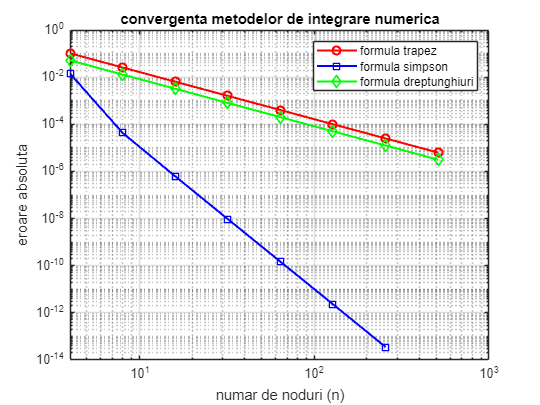


% plotam convergenta (log-log)
figure;
loglog(n_values, erori_trapez, 'ro-', 'LineWidth', 1.5);
hold on;
loglog(n_values, erori_simpson, 'bs-', 'LineWidth', 1.5);
loglog(n_values, erori_dreptunghiuri, 'gd-', 'LineWidth', 1.5);
grid on;
legend('formula trapez', 'formula simpson', 'formula dreptunghiuri');
xlabel('numar de noduri (n)');
ylabel('eroare absoluta');
title('convergenta metodelor de integrare numerica');